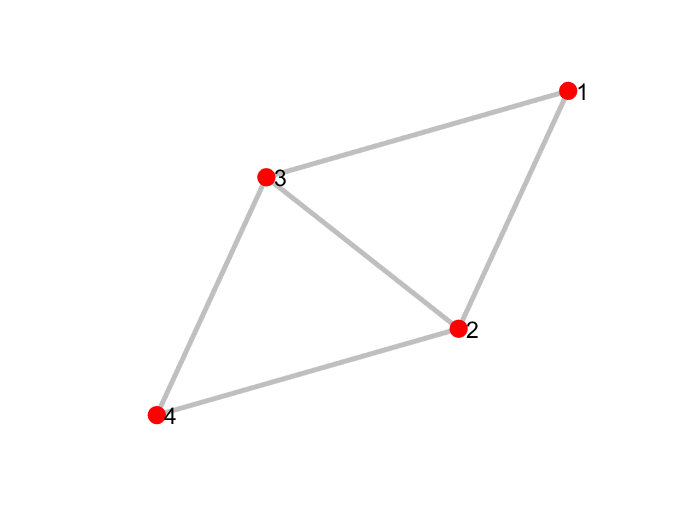

clear


EdgesList = [1,2;2,3;3,4;2,4;1,3]; % try a larger list
n = max(EdgesList(:));
Gamma = full(sparse(EdgesList,fliplr(EdgesList),ones(size(EdgesList)),n,n));
% perm_v = [3,2,1,4];
% perm_v = [2,3,1,4];
perm_v = 1:n;
Gamma = Gamma(perm_v,perm_v);
Tableau = [eye(size(Gamma)),Gamma];

figure;
plot(graph(Gamma),'MarkerSize',10,'NodeColor','r','EdgeColor',0.5*[1,1,1], ...
    'LineWidth',3,'NodeFontSize',14);
axis off



% ---- initialize the Generator: ------
Generators.Tableau = Tableau;
Generators.SignVector = zeros(size(Tableau,1),1);


%%%%%%%%%

Tableau_Phi = Generators.Tableau;  % load any Tableau here
SignVector = Generators.SignVector; % Signs for generators in Tableau

n_p = size(Generators.Tableau,1);
h0 = heightfunc(Generators.Tableau,'pure'); % the original height function
n_e = max(h0);
n = n_p + n_e;

GenCell = cell(n_p,4);

%-------structure variables that record protocol------------
% Operation is the inverted operation on stabilizer operators,
% but Operation is a normal operation on state. (Finally written on report)
Operation.photons.Up.type = cell(n_p,1);
Operation.emitters.Ue.type = cell(n_p,1); % n_p rounds
Operation.emitters.Ue.site = cell(n_p,1);
Operation.emitters.W.type = cell(n_p,1);
Operation.emitters.W.site = cell(n_p,1);
Operation.emitters.W0.type = cell(1,1);
Operation.emitters.W0.site = cell(1,1);
Operation.emitters.EmissionSite = cell(n_p,1);
Operation.emitters.MeasurementSite = cell(n_p,1); % intermidiate measurement, finall measurement not included
% Operation.photons.Nozzlesite = cell(n_e,1); % nozzle photons for PMS

% InvOperation is the inverted operation on state, (call this on simulator)
% but InvOperation is a normal operation on stablizer operators.
InvOperation.photons.Up.type = cell(n_p,1);
InvOperation.emitters.Ue.type = cell(n_p,1); % n_p rounds
InvOperation.emitters.Ue.site = cell(n_p,1);
InvOperation.emitters.W.type = cell(n_p,1);
InvOperation.emitters.W.site = cell(n_p,1);
InvOperation.emitters.W0.type = cell(1,1);
InvOperation.emitters.W0.site = cell(1,1);
InvOperation.emitters.EmissionSite = cell(n_p,1);
InvOperation.emitters.MeasurementSite = cell(n_p,1); % intermidiate measurement, finall measurement not included
%---------------------------------------

Tableau_temp = zeros(n,2*n); % the final Tableau, which is the first tableau in photon absorption process
Tableau_temp(1:n_p, [1:n_p, n+(1:n_p)]) = Tableau_Phi; % evaluate the subblock
Tableau_temp(n_p + (1:n_e),n + n_p + (1:n_e)) = eye(n_e); % g = +Z for all emitters
G_temp.Tableau = Tableau_temp; % target final Generator
G_temp.SignVector = [SignVector ; zeros(n_e,1)];

G_f = G_temp;


for k = 0:(n_p-1)
    j = n_p - k;
    
    [~,R] = ECHELON_TABLEAU(G_temp.Tableau); % Echelon gauge
    
    
    G_temp = GaugeTransformation(G_temp,R);
    bigram = Tableau2Bigram(G_temp.Tableau);
    h = heightfunc(G_temp.Tableau,'pure'); % PAI (1)
    
    %%%%%*****
    GenCell{k+1,1} = G_temp;
    %%%%%*****
    
    if j > 1
        dh = h(j) - h(j-1);
    else
        dh = h(j);
    end
    switch dh
        case {0,1}      % PAI (2a)
            % skip
        case -1         % PAI (2b)
            % %             fprintf(1,'Try to fix the descending point ... j = %2d\n', j);
            b = find(bigram(:,1)>n_p, 1, 'first');
            %             b = find(bigram(:,1)>n_p, 1, 'last');
            g_b = G_temp.Tableau(b,:);
            % find the nontrivial emitter position on g_b
            e_v_b = find(g_b(n_p+(1:n_e)) + g_b(n+n_p+(1:n_e)) ~= 0);
            mu = n_p + e_v_b(1); % can be other choices
            
            gate_ct = 1;
            switch numel(e_v_b)
                case 1 % turn every Pauli matrix as X
                    s = mu; % site of operation
                    if g_b([s, n + s]) == [1,0]  % if it is X
                        % do nothing
                        gate_str = 'I';
                        gate_str_inv = 'I';
                    elseif g_b([s, n + s]) == [1,1] % if it is Y
                        gate_str = 'P';
                        gate_str_inv = 'PZ';
                    elseif g_b([s, n + s]) == [0,1] % if it is Z
                        gate_str = 'H';
                        gate_str_inv = 'H';
                    end
                    G_temp = CliffordOperation(G_temp,gate_str,s);
                    Operation.emitters.W.type{j,gate_ct} = gate_str;
                    Operation.emitters.W.site{j,gate_ct} = s;
                    InvOperation.emitters.W.type{j,gate_ct} = gate_str_inv;
                    InvOperation.emitters.W.site{j,gate_ct} = s;
                    gate_ct = gate_ct + 1;
                otherwise % numel(e_v_b) > 1, % first make them all X
                    % turn every Pauli matrix as X
                    for i_e = 1:numel(e_v_b)
                        s = n_p + e_v_b(i_e);
                        if g_b([s, n + s]) == [1,0]  % if it is X
                            % do nothing
                            gate_str = 'I';
                            gate_str_inv = 'I';
                        elseif g_b([s, n + s]) == [1,1] % if it is Y
                            gate_str = 'P';
                            gate_str_inv = 'PZ';
                        elseif g_b([s, n + s]) == [0,1] % if it is Z
                            gate_str = 'H';
                            gate_str_inv = 'H';
                        end
                        G_temp = CliffordOperation(G_temp,gate_str,s);
                        Operation.emitters.W.type{j,gate_ct} = gate_str;
                        Operation.emitters.W.site{j,gate_ct} = s;
                        InvOperation.emitters.W.type{j,gate_ct} = gate_str_inv;
                        InvOperation.emitters.W.site{j,gate_ct} = s;
                        gate_ct = gate_ct + 1;
                    end
                    % Control gates on emitters: CNOT X-X pairs becomes X-I:
                    e_v_b_remain = setdiff(e_v_b,mu - n_p);
                    for i_e = 1:numel(e_v_b_remain)
                        s = n_p + e_v_b_remain(i_e);
                        gate_str = 'CNOT';
                        gate_str_inv = 'CNOT';
                        G_temp = CliffordOperation(G_temp,gate_str,[mu,s]);
                        Operation.emitters.W.type{j,gate_ct} = gate_str;
                        Operation.emitters.W.site{j,gate_ct} = [mu,s];
                        InvOperation.emitters.W.type{j,gate_ct} = gate_str_inv;
                        InvOperation.emitters.W.site{j,gate_ct} = [mu,s];
                        gate_ct = gate_ct + 1;
                    end
            end
            % turn (-)X as (+)X, if the sign is incorrect
            if G_temp.SignVector(b) == 1
                gate_str = 'Z';
                gate_str_inv = 'Z';
                G_temp = CliffordOperation(G_temp,gate_str,mu);
                Operation.emitters.W.type{j,gate_ct} = gate_str;
                Operation.emitters.W.site{j,gate_ct} = mu;
                InvOperation.emitters.W.type{j,gate_ct} = gate_str_inv;
                InvOperation.emitters.W.site{j,gate_ct} = mu;
                gate_ct = gate_ct + 1;
            end
            % turn (+)I-X as (+)X-X by CNOT, which will 'boost' h(x)
            InvOperation.emitters.MeasurementSite{j} = mu;
            Operation.emitters.MeasurementSite{j} = mu;
            G_temp = CliffordOperation(G_temp,'CNOT',[mu,j]);
            
            [~,R] = ECHELON_TABLEAU(G_temp.Tableau); % Echelon gauge
            G_temp = GaugeTransformation(G_temp,R);
            bigram = Tableau2Bigram(G_temp.Tableau);
    end
    
    %%%%%*****
    GenCell{k+1,2} = G_temp; % revered measurement
    %%%%%*****
    
    a = find(bigram(:,1) == j, 1, 'last');  % find the index of g_a
    g_a = G_temp.Tableau(a,:); %
    % LC on photon,
    % % turn the Pauli matrix to Z:
    if g_a([j, n + j]) == [1,0] % if it is X
        gate_str = 'H';
        gate_str_inv = 'H';
    elseif g_a([j, n + j]) == [1,1] % if it is Y
        gate_str = 'PH';
        gate_str_inv = 'HPZ';
    elseif g_a([j, n + j]) == [0,1] % if it is Z
        gate_str = 'I';
        gate_str_inv = 'I';
    end
    G_temp = CliffordOperation(G_temp,gate_str,j);
    Operation.photons.Up.type{j} = gate_str;
    InvOperation.photons.Up.type{j} = gate_str_inv;
    
    e_v_a = find(g_a(n_p+(1:n_e)) + g_a(n+n_p+(1:n_e)) ~= 0); % find the nontrivial emitter position on g_a
    eta = n_p + e_v_a(1); % can be other choices
    
    Operation.emitters.EmissionSite{j} = eta;
    InvOperation.emitters.EmissionSite{j} = eta;
    
    % Clifford operations on emitters: find U_e
    gate_ct = 1; % counter for history recording
    switch numel(e_v_a)
        case 1
            % turn the Pauli matrix to Z
            s = eta;
            if g_a([s, n + s]) == [1,0] % if it is X
                gate_str = 'H';
                gate_str_inv = 'H';
            elseif g_a([s, n + s]) == [1,1] % if it is Y
                gate_str = 'PH';
                gate_str_inv = 'HPZ';
            elseif g_a([s, n + s]) == [0,1] % if it is Z
                % do nothing
                gate_str = 'I';
                gate_str_inv = 'I';
            end
            G_temp = CliffordOperation(G_temp,gate_str,s);
            Operation.emitters.Ue.type{j,gate_ct} = gate_str;
            Operation.emitters.Ue.site{j,gate_ct} = s;
            InvOperation.emitters.Ue.type{j,gate_ct} = gate_str_inv;
            InvOperation.emitters.Ue.site{j,gate_ct} = s;
            gate_ct = gate_ct + 1;
        otherwise % if there are more than one non-trivial Paulimatrices
            % first make them all Z
            for i_e = 1:numel(e_v_a)  % LC on emitters
                s = n_p + e_v_a(i_e);
                g_a_emitterpauli = g_a([s, n + s]);
                if g_a_emitterpauli == [1,0] % if it is X
                    gate_str = 'H';
                    gate_str_inv = 'H';
                elseif g_a_emitterpauli == [1,1] % if it is Y
                    gate_str = 'PH';
                    gate_str_inv = 'HPZ';
                elseif g_a_emitterpauli == [0,1] % if it is Z
                    % do nothing
                    gate_str = 'I';
                    gate_str_inv = 'I';
                end
                G_temp = CliffordOperation(G_temp,gate_str,s);
                Operation.emitters.Ue.type{j,gate_ct} = gate_str;
                Operation.emitters.Ue.site{j,gate_ct} = s;
                InvOperation.emitters.Ue.type{j,gate_ct} = gate_str_inv;
                InvOperation.emitters.Ue.site{j,gate_ct} = s;
                gate_ct = gate_ct + 1;
            end
            % Control gates within emitters: CNOT Z-Z pairs becomes Z-I
            e_v_a_remain = setdiff(e_v_a, eta - n_p); % target emitters qubit
            for i_e = 1:numel(e_v_a_remain)
                s = n_p + e_v_a_remain(i_e);
                gate_str = 'CNOT';
                gate_str_inv = 'CNOT';
                G_temp = CliffordOperation(G_temp,gate_str,[s,eta]);
                Operation.emitters.Ue.type{j,gate_ct} = gate_str;
                Operation.emitters.Ue.site{j,gate_ct} = [s,eta];
                InvOperation.emitters.Ue.type{j,gate_ct} = gate_str_inv;
                InvOperation.emitters.Ue.site{j,gate_ct} = [s,eta];
                gate_ct = gate_ct + 1;
            end
    end
    
    
    % Correct the minus sign of g_a = (-)Z-Z to (+)Z-Z, by flipping the emitter:
    % (flipping the photon qubit seems available)
    if G_temp.SignVector(a) == 1
        gate_str = 'X';
        gate_str_inv = 'X';
        G_temp = CliffordOperation(G_temp,gate_str,eta);
        Operation.emitters.Ue.type{j,gate_ct} = gate_str;
        Operation.emitters.Ue.site{j,gate_ct} = eta;
        InvOperation.emitters.Ue.type{j,gate_ct} = gate_str_inv;
        InvOperation.emitters.Ue.site{j,gate_ct} = eta;
        gate_ct = gate_ct + 1;
    end
    
    %%%%%*****
    GenCell{k+1,3} = G_temp; % revered measurement
    %%%%%*****
    
    %%%%%
    % Absorption (inverted emission):
    G_temp = CliffordOperation(G_temp,'CNOT',[eta,j]);
    %%%%
    
    
    
    R = eye(n);
    R(:,a) =  (G_temp.Tableau(:,j) + G_temp.Tableau(:,n+j))~=0 ;
    G_temp = GaugeTransformation(G_temp,R);
    
    %%%%%*****
    GenCell{k+1,4} = G_temp; % revered measurement
    %%%%%*****
    
end

%-----------------------------------
% Find W0:

[~,R] = ECHELON_TABLEAU(G_temp.Tableau); % Echelon gauge
G_temp = GaugeTransformation(G_temp,R);
% bigram = Tableau2Bigram(G_temp.Tableau);
gate_ct = 1;
for i_r = (1:n_e) + n_p
    g_c = G_temp.Tableau(i_r,:);
    e_v_c = find(g_c(n_p+(1:n_e)) + g_c(n+n_p+(1:n_e)) ~= 0); % find the nontrivial position on g_c
    kappa = n_p + e_v_c(1);
    switch numel(e_v_c)
        case 1
            % turn Pauli matrix as Z
            if g_c([kappa, n + kappa]) == [1,0] % if it is X
                gate_str = 'H';
                gate_str_inv = 'H';
            elseif g_c([kappa, n + kappa]) == [1,1] % if it is Y
                gate_str = 'PH';
                gate_str_inv = 'HPZ';
            elseif g_c([kappa, n + kappa]) == [0,1] % if it is Z
                % do nothing
                gate_str = 'I';
                gate_str_inv = 'I';
            else
                error('Unexpected value!')
            end
            G_temp = CliffordOperation(G_temp,gate_str,kappa);
            Operation.emitters.W0.type{1,gate_ct} = gate_str;
            Operation.emitters.W0.site{1,gate_ct} = kappa;
            InvOperation.emitters.W0.type{1,gate_ct} = gate_str_inv;
            InvOperation.emitters.W0.site{1,gate_ct} = kappa;
            gate_ct = gate_ct + 1;
        otherwise  % numel(e_v_c) > 1
            for i_e = 1:numel(e_v_c)  % LC on emitters
                % turn every Pauli matrix as X
                s = n_p + e_v_c(i_e);
                g_c_emitterpauli = g_c([s, n + s]);
                % turn Pauli matrix as X
                if g_c_emitterpauli == [1,0] % if it is X
                    % do nothing
                    gate_str = 'I';
                    gate_str_inv = 'I';
                elseif g_c_emitterpauli == [1,1] % if it is Y
                    gate_str = 'P';
                    gate_str_inv = 'PZ';
                elseif g_c_emitterpauli == [0,1] % if it is Z
                    gate_str = 'H';
                    gate_str_inv = 'H';
                end
                G_temp = CliffordOperation(G_temp,gate_str,s);
                Operation.emitters.W0.type{1,gate_ct} = gate_str;
                Operation.emitters.W0.site{1,gate_ct} = s;
                InvOperation.emitters.W0.type{1,gate_ct} = gate_str_inv;
                InvOperation.emitters.W0.site{1,gate_ct} = s;
                gate_ct = gate_ct + 1;
            end
            % Control gates on emitters: CNOT X-X pairs becomes X-I
            e_v_c_remain = setdiff(e_v_c,kappa - n_p); % target emitters qubit
            for i_e = 1:numel(e_v_c_remain)
                s = n_p + e_v_c_remain(i_e);
                gate_str = 'CNOT';
                gate_str_inv = 'CNOT';
                G_temp = CliffordOperation(G_temp,gate_str,[kappa,s]);
                Operation.emitters.W0.type{1,gate_ct} = gate_str;
                Operation.emitters.W0.site{1,gate_ct} = [kappa,s];
                InvOperation.emitters.W0.type{1,gate_ct} = gate_str_inv;
                InvOperation.emitters.W0.site{1,gate_ct} = [kappa,s];
                gate_ct = gate_ct + 1;
            end
            
            % Recover X as Z
            gate_str = 'H';
            gate_str_inv = 'H';
            G_temp = CliffordOperation(G_temp,gate_str,kappa);
            Operation.emitters.W0.type{1,gate_ct} = gate_str;
            Operation.emitters.W0.site{1,gate_ct} = kappa;
            InvOperation.emitters.W0.type{1,gate_ct} = gate_str_inv;
            InvOperation.emitters.W0.site{1,gate_ct} = kappa;
            gate_ct = gate_ct + 1;
    end
    
    % doing row transformation, which eliminate all other Zs in the same column
    R = logical(eye(n));
    R(:,i_r) = all(G_temp.Tableau(:,[kappa,n+kappa]) == [0,1],2);
    G_temp = GaugeTransformation(G_temp,R);
    
    % % %     figure;
    % % %     VisualizeTableau(TableauSelfInspection(G_temp.Tableau),'PauliStringOnly');
    % % %     line([n_p,n_p]+0.5,[0,n+1], 'Color', 'k');
    % % %     title({['before absorbing'];['the ',num2str(i_r- n_p),'-th emitter']});
end

[~,R] = ECHELON_TABLEAU(G_temp.Tableau); % Echelon gauge
G_temp = GaugeTransformation(G_temp,R);
% so far the Tableau is all Z, only the sign of emitters need to be fixed:
for i_e = (1:n_e) + n_p
    if G_temp.SignVector(i_e) == 1
        gate_str = 'X';
        gate_str_inv = 'X';
    else
        gate_str = 'I';
        gate_str_inv = 'I';
    end
    G_temp = CliffordOperation(G_temp,gate_str,i_e);
    Operation.emitters.W0.type{1,gate_ct} = gate_str;
    Operation.emitters.W0.site{1,gate_ct} = i_e;
    InvOperation.emitters.W0.type{1,gate_ct} = gate_str_inv;
    InvOperation.emitters.W0.site{1,gate_ct} = i_e;
    gate_ct = gate_ct + 1;
end




if all(G_temp.Tableau == [zeros(n),eye(n)],'all') && all(G_temp.SignVector == [zeros(n,1)],'all')
    % fprintf('The Generators set of ''photon + emitter'' has recovered as ''standard generator set''! \n');
    fprintf(1,'\t** The protocol is SOLVED correctly! ** \n');
else
    % fprintf('The Generators set of ''photon + emitter'' is NOT yet a ''standard generator set''! \n');
    error('\t** The protocol is NOT solved correctly! **   \n');
end

	** The protocol is SOLVED correctly! ** 



%----
Stat.PhotonsNumber = n_p;
Stat.EmittersNumber = n_e;
Stat.HeightFunc = h0;
Stat.OperationNumber.Ue = numel( find( ...
    ~cellfun('isempty', Operation.emitters.Ue.type) .* ~strcmp(Operation.emitters.Ue.type,'I')));
Stat.OperationNumber.W = numel( find( ...
    ~cellfun('isempty', Operation.emitters.W.type) .* ~strcmp(Operation.emitters.W.type,'I')));
Stat.OperationNumber.W0 = numel( find( ...
    ~cellfun('isempty', Operation.emitters.W0.type) .* ~strcmp(Operation.emitters.W0.type,'I')));
Stat.OperationNumber.AllEmitterUnitaries = Stat.OperationNumber.Ue + Stat.OperationNumber.W + Stat.OperationNumber.W0;
Stat.OperationNumber.Measurement = numel(find(~cellfun('isempty',Operation.emitters.MeasurementSite)));
Stat.OperationNumber.CNOT =  numel(find(strcmp(Operation.emitters.Ue.type,'CNOT'))) ...
    + numel(find(strcmp(Operation.emitters.W.type,'CNOT'))) + numel(find(strcmp(Operation.emitters.W0.type,'CNOT')));
%----


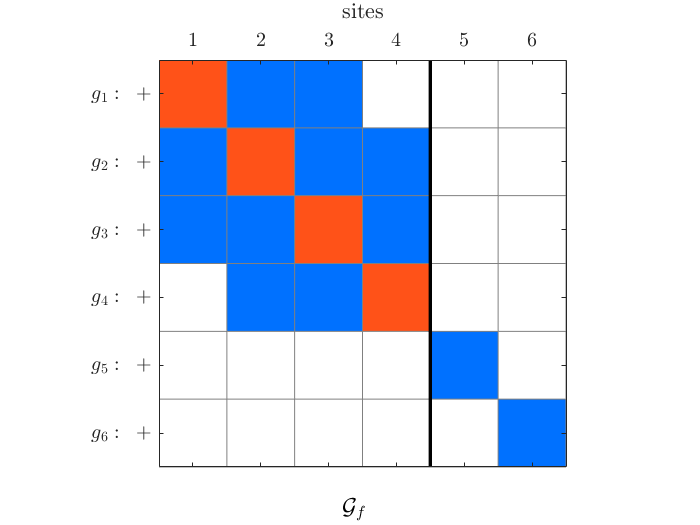

figure;

% % ha = tight_subplot(1,2,[.02 .1],[.01 .2],[.01 .05]);
% % % axes(ha(1));
% % % plot(graph(Gamma),'MarkerSize',8,'NodeColor','r','EdgeColor',0.5*[1,1,1],'LineWidth',3,...
% % %     'NodeFontSize',12,'XData',[0,1,0,1],'YData',[0,0,-1,-1]);
% % % axis off
% % % daspect([1,1,1]);
% % % xlim([-0.2,2]);
% % % ylim([-2,0]);
% % 
% % axes(ha(1));
PlotGeneratorsArray(G_f,n_p);
text(0.45,-0.1,'$\mathcal{G}_f$','Interpreter','latex','Units','normalized','FontSize',14);
xticks(1:n);
xticklabels(num2cell(1:n)');
yticks(1:n)
ylabelCell = cell(1,n);
for i = 1:n
    ylabelCell{1,i} = ['$g_',num2str(i),':\;\; +$'];
end
yticklabels(ylabelCell);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
xlabel('$\mathrm{sites}$','Interpreter','latex','FontSize',12)


% % axes(ha(2));
% % CC = [0,0,0;
% %     1,1,1;
% %     1, 0.3250, 0.0980;
% %     0.4660, 1, 0.1880;
% %     0, 0.4470, 1];
% % x0 = [0,1,1,0];
% % y0 = [0,0,1,1];
% % fill(x0,y0+2,CC(2,:)); hold on
% % fill(x0,y0,CC(3,:)); hold on
% % fill(x0,y0-2,CC(4,:)); hold on
% % fill(x0,y0-4,CC(5,:)); hold on
% % 
% % xtxt0 = -2.0;
% % ytxt0 = 2.5;
% % fs=14;
% % text(xtxt0,ytxt0,'$\;I:$','Interpreter','latex','FontSize',fs);
% % text(xtxt0,ytxt0-2,'$X:$','Interpreter','latex','FontSize',fs);
% % text(xtxt0,ytxt0-4,'$Y:$','Interpreter','latex','FontSize',fs);
% % text(xtxt0,ytxt0-6,'$Z:$','Interpreter','latex','FontSize',fs);
% % 
% % daspect([10,10,1])
% % xlim([-0.0,12]);
% % ylim([-6,3]);
% % axis off

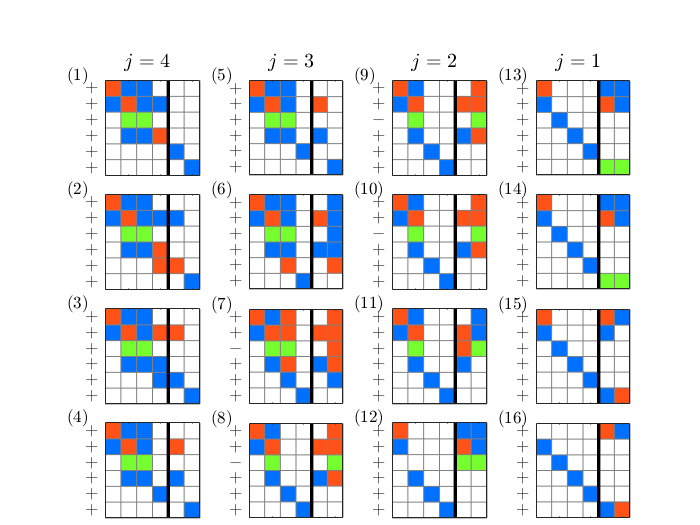


figure;
ha = tight_subplot(size(GenCell,2),n_p,[.03 .07],[.01 .15],[.15 .1]);
LabelTable = reshape(1:numel(GenCell),[4,n_p])';
for ii = 1:numel(GenCell)
    axes(ha(ii));
    PlotGeneratorsArray(GenCell{ii},n_p);
    xticklabels({})
    text(-0.4,1.05,['$(',num2str(LabelTable(ii)),')$'],'Units','normalized','FontSize',10,'Interpreter','latex');
    if ii <= n_p
        %        title(['$j=',num2str(n_p - ii + 1),'$'],'Interpreter','latex','FontSize',20);
        text(0.2,1.2,['$j=',num2str(n_p - ii + 1),'$'],'Interpreter','latex','Units','normalized','FontSize',12);
    end
    % % %     xx = -0.75;
    % % %     switch LabelTable(ii)
    % % %         case 1
    % % %         text(xx,0.5,['$\mathbf{(i)}$'],'Interpreter','latex','Units','normalized','FontSize',12);
    % % %         case 2
    % % %         text(xx,0.5,['$\mathbf{(ii)}$'],'Interpreter','latex','Units','normalized','FontSize',12);
    % % %         case 3
    % % %         text(xx,0.5,['$\mathbf{(iii)}$'],'Interpreter','latex','Units','normalized','FontSize',12);
    % % %         case 4
    % % %         text(xx,0.5,['$\mathbf{(iv)}$'],'Interpreter','latex','Units','normalized','FontSize',12);
    % % %     end
end

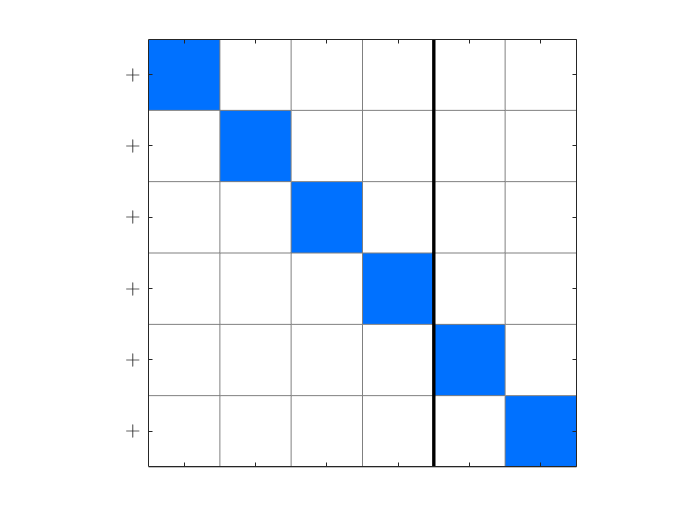


figure;
PlotGeneratorsArray(G_temp,n_p);
xticklabels({})
set(gca,'TickLabelInterpreter','latex','FontSize',12)

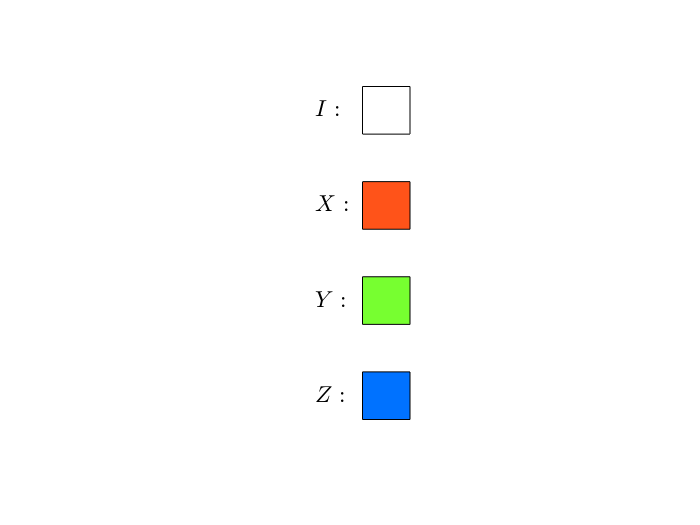

figure;
CC = [0,0,0;
    1,1,1;
    1, 0.3250, 0.0980;
    0.4660, 1, 0.1880;
    0, 0.4470, 1];
x0 = [0,1,1,0];
y0 = [0,0,1,1];
fill(x0,y0+2,CC(2,:)); hold on
fill(x0,y0,CC(3,:)); hold on
fill(x0,y0-2,CC(4,:)); hold on
fill(x0,y0-4,CC(5,:)); hold on

xtxt0 = -1;
ytxt0 = 2.5;
fs=14;
text(xtxt0,ytxt0,'$I:$','Interpreter','latex','FontSize',fs);
text(xtxt0,ytxt0-2,'$X:$','Interpreter','latex','FontSize',fs);
text(xtxt0,ytxt0-4,'$Y:$','Interpreter','latex','FontSize',fs);
text(xtxt0,ytxt0-6,'$Z:$','Interpreter','latex','FontSize',fs);

daspect([1,1,1])
xlim([-2,2]);
ylim([-5,4]);
axis off


% figure;
% a = 5;
% plot(graph(Gamma),'MarkerSize',8,'NodeColor','r','EdgeColor',0.5*[1,1,1],'LineWidth',3,...
%     'NodeFontSize',12,'XData',[0,1,0,1],'YData',[0,0,-1,-1]);
% axis off
% daspect([1,1,1]);
% xlim(a*[0,1]);
% ylim(a*[-1,0]);
% % % % % savepath_graph = ['slashsquare1.pdf'];
% % % % % saveas(gca,savepath_graph);
% % % % % system(['pdfcrop ',savepath_graph,' ',savepath_graph]);
% 
% 
% figure;
% a = 5;
% p=plot(graph(Gamma),'MarkerSize',8,'NodeColor','r','EdgeColor',0.5*[1,1,1],'LineWidth',3,...
%     'NodeFontSize',12,'XData',[0,1,0,1],'YData',[0,0,-1,-1]);
% axis off
% daspect([1,1,1]);
% xlim(a*[0,1]);
% ylim(a*[-1,0]);
% labelnode(p,1:4,{'3','2','1','4'});
% % % % % savepath_graph = ['slashsquare2.pdf'];
% % % % % saveas(gca,savepath_graph);
% % % % % system(['pdfcrop ',savepath_graph,' ',savepath_graph]);

function [] = PlotGeneratorsArray(Gen,n_p)
Tableau = Gen.Tableau;
SignVector = Gen.SignVector;
n = size(Tableau,1);
PauliStr=zeros(n,n);
for i_r = 1:n
    % easy to read TABLEAU, with 0->I, 1->X, 2->Y, 3->Z
    PauliStr(i_r,:) = abs([1,-3]*[Tableau(i_r,1:n);Tableau(i_r,(1:n)+n)]);
end
SignCell = cell(1,n);
for i_r = 1:n
    switch SignVector(i_r)
        case 0
            SignCell{1,i_r} = '$+$';
        case 1
            SignCell{1,i_r} = '$-$';
    end
end
%%%%%
% latest version: 01/15/2021
% % CC = [0,0,0;
% %     1,1,1;
% %     1,0,0;
% %     0,1,0;
% %     0,0,1];
CC = [0,0,0;
    1,1,1;
    1, 0.3250, 0.0980;
    0.4660, 1, 0.1880;
    0, 0.4470, 1];
imagesc(PauliStr);
colormap(gca,CC([2:5],:));
caxis([0,3]);
daspect([1,1,1]);
set(gca,'xaxisLocation','top');


yticks(1:n);
yticklabels(SignCell);
set(gca,'TickLabelInterpreter','latex','FontSize',10)
for i_c = 1:n
    line([i_c,i_c]+0.5,[0,n+1], 'Color', 0.5*[1,1,1]); hold on
    line([0,n+1],[i_c,i_c]+0.5, 'Color', 0.5*[1,1,1]); hold on
end
line([n_p,n_p]+0.5,[0,n+1], 'Color', 'k','LineWidth',2);
end

function [ha, pos] = tight_subplot(Nh, Nw, gap, marg_h, marg_w)
% tight_subplot creates "subplot" axes with adjustable gaps and margins
%
% [ha, pos] = tight_subplot(Nh, Nw, gap, marg_h, marg_w)
%
%   in:  Nh      number of axes in hight (vertical direction)
%        Nw      number of axes in width (horizontaldirection)
%        gap     gaps between the axes in normalized units (0...1)
%                   or [gap_h gap_w] for different gaps in height and width
%        marg_h  margins in height in normalized units (0...1)
%                   or [lower upper] for different lower and upper margins
%        marg_w  margins in width in normalized units (0...1)
%                   or [left right] for different left and right margins
%
%  out:  ha     array of handles of the axes objects
%                   starting from upper left corner, going row-wise as in
%                   subplot
%        pos    positions of the axes objects
%
%  Example: ha = tight_subplot(3,2,[.01 .03],[.1 .01],[.01 .01])
%           for ii = 1:6; axes(ha(ii)); plot(randn(10,ii)); end
%           set(ha(1:4),'XTickLabel',''); set(ha,'YTickLabel','')
% Pekka Kumpulainen 21.5.2012   @tut.fi
% Tampere University of Technology / Automation Science and Engineering
if nargin<3; gap = .02; end
if nargin<4 || isempty(marg_h); marg_h = .05; end
if nargin<5; marg_w = .05; end
if numel(gap)==1
    gap = [gap gap];
end
if numel(marg_w)==1
    marg_w = [marg_w marg_w];
end
if numel(marg_h)==1
    marg_h = [marg_h marg_h];
end
axh = (1-sum(marg_h)-(Nh-1)*gap(1))/Nh;
axw = (1-sum(marg_w)-(Nw-1)*gap(2))/Nw;
py = 1-marg_h(2)-axh;
% ha = zeros(Nh*Nw,1);
ii = 0;
for ih = 1:Nh
    px = marg_w(1);
    
    for ix = 1:Nw
        ii = ii+1;
        ha(ii) = axes('Units','normalized', ...
            'Position',[px py axw axh], ...
            'XTickLabel','', ...
            'YTickLabel','');
        px = px+axw+gap(2);
    end
    py = py-axh-gap(1);
end
if nargout > 1
    pos = get(ha,'Position');
end
ha = ha(:);
end



